% EDIT THESE TO PLAY: 

% Where to save: 
outFolder = [userFolder filesep 'toolboxes' filesep 'qpfmri' filesep 'tests' filesep 'Results'];

% Set the seed to have repeatable control.
seed = 554;
pinkNoise = 1;
% You can also add in simulation params here. 
% Param1 = exponent
% Param2 = semiSat
% Param3 = beta (keep this 1)
% Param4 = sigma (keep this .01, but you'll set noise below).
simulatedPsiParams = [];
simulatedPsiParams = [5, .3, 1, .01];

% Noise in standard deviations of maxBOLD
noiseSD = .3;

% headroom
%headroom = 0;

% Number of trials to run.
nTrials = 20;

% Initial baseline and max BOLD trials.
% Max BOLD trials are not necessary with maxBOLD locked, but at least 1
% baseline is required.
baselineMaxBOLDInitial = 1;


% The following options can be edited, but probably don't make much
% difference.

% Provide a model handle
model = @nakaRushton;

% Specify the parameter domain. Each value must correspond to a parameter
% expected by the model. 
paramsDomain = struct;
paramsDomain.exponent = makeDomain(-1,1,15,'spacing','log');
paramsDomain.semiSat = makeDomain(.1,1,15);

% We are locking in beta right now. 
paramsDomain.beta = makeDomain(.75,1.25,1,'spacing','zeno');
% To enable maxBOLD, use this line and change the line below to something besides 1.5:
%paramsDomain.beta = makeDomain(.75,1.25,11,'spacing','zeno');
%maxBOLDInitialGuess = 1.5;

% Sigma in the parameter domain is searching for noiseSD
paramsDomain.sigma = makeDomain(0.01,1,20);

% Specify a stimulus domain and whether it spaced linear or log.
stimulusDomain = {makeDomain(.0001,1,25)};
stimulusDomainSpacing = 'lin';
baselineStimulus = min(stimulusDomain{:});

% Set the number of outcome categories / bins.
nOutcomes = 21;

%How long the trials are (in seconds).
trialLength = 24;

% Do you want to see plots?
showPlots = true; 

% Again, important to lock in BOLD for the moment. 
% The range of BOLD signal to simulate (e.g., from baseline to maximum BOLD)
maxBOLDSimulated = 1.5;
maxBOLDInitialGuess = 1.5;


% Allow Q+ to control the stimuli or not (false).
qpPres = false;

date = datestr(now,'yyyymmddhhMMss');

% Save outNum based on values above
formatSpec = 'pink-%0.2f_noise-%0.4f_qplus-%s_nOutcomes-%d_trials-%d_seed-%d_date-%s';
outNum = sprintf(formatSpec,pinkNoise,noiseSD,num2str(qpPres),nOutcomes,nTrials,seed,date);


[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'pinkNoise',pinkNoise,'baselineStimulus',baselineStimulus,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams,...,
'outFolder',outFolder,'outNum',outNum);

fprintf('Saving figure as %s',outNum);

Saving figure as pink-1.00_noise-0.3000_qplus-0_nOutcomes-21_trials-20_seed-554_date-20220207132109

Initial random call 0.9691
Random call after seed 0.4375


Initializing Q+. This may take a minute...
Elapsed time is 0.536201 seconds.


Simulated parameters:
exponent: 5.000 semiSat: 0.300 beta: 1.000 sigma: 0.010 
Noise in the simulation is set at 0.900 relative to a maxBOLD of 1.50

Trial 1: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 0.517 semiSat: 0.100 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 2: random Stimulus Selection
Stimulus: 0.083
Output value -0.176

Q+ parameters
exponent: 2.192 semiSat: 0.581 beta: 1.000 sigma: 0.075 
maxBOLD estimate = 1.500




Trial 3: random Stimulus Selection
Stimulus: 0.458
Output value 0.882

Q+ parameters
exponent: 3.565 semiSat: 0.414 beta: 1.000 sigma: 0.057 
maxBOLD estimate = 1.500




Trial 4: random Stimulus Selection
Stimulus: 0.833
Output value 1.588

Q+ parameters
exponent: 5.295 semiSat: 0.408 beta: 1.000 sigma: 0.056 
maxBOLD estimate = 1.500




Trial 5: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.500

Q+ parameters
exponent: 6.577 semiSat: 0.419 beta: 1.000 sigma: 0.051 
maxBOLD estimate = 1.500




Trial 6: random Stimulus Selection
Stimulus: 0.500
Output value 1.588

Q+ parameters
exponent: 9.685 semiSat: 0.413 beta: 1.000 sigma: 0.087 
maxBOLD estimate = 1.500




Trial 7: random Stimulus Selection
Stimulus: 0.167
Output value 0.000

Q+ parameters
exponent: 8.737 semiSat: 0.381 beta: 1.000 sigma: 0.090 
maxBOLD estimate = 1.500




Trial 8: random Stimulus Selection
Stimulus: 0.958
Output value 1.147

Q+ parameters
exponent: 3.798 semiSat: 0.291 beta: 1.000 sigma: 0.123 
maxBOLD estimate = 1.500




Trial 9: random Stimulus Selection
Stimulus: 0.708
Output value 0.706

Q+ parameters
exponent: 8.162 semiSat: 0.303 beta: 1.000 sigma: 0.241 
maxBOLD estimate = 1.500




Trial 10: baseline Stimulus Selection
Stimulus: 0.000
Output value -0.176

Q+ parameters
exponent: 3.792 semiSat: 0.194 beta: 1.000 sigma: 0.098 
maxBOLD estimate = 1.500




Trial 11: random Stimulus Selection
Stimulus: 1.000
Output value 1.147

Q+ parameters
exponent: 4.304 semiSat: 0.205 beta: 1.000 sigma: 0.115 
maxBOLD estimate = 1.500




Trial 12: random Stimulus Selection
Stimulus: 0.250
Output value 0.529

Q+ parameters
exponent: 4.003 semiSat: 0.256 beta: 1.000 sigma: 0.118 
maxBOLD estimate = 1.500




Trial 13: random Stimulus Selection
Stimulus: 0.292
Output value 1.147

Q+ parameters
exponent: 4.131 semiSat: 0.228 beta: 1.000 sigma: 0.112 
maxBOLD estimate = 1.500




Trial 14: random Stimulus Selection
Stimulus: 0.167
Output value -0.176

Q+ parameters
exponent: 5.986 semiSat: 0.264 beta: 1.000 sigma: 0.125 
maxBOLD estimate = 1.500




Trial 15: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.588

Q+ parameters
exponent: 5.420 semiSat: 0.255 beta: 1.000 sigma: 0.115 
maxBOLD estimate = 1.500




Trial 16: random Stimulus Selection
Stimulus: 0.542
Output value 1.588

Q+ parameters
exponent: 5.900 semiSat: 0.262 beta: 1.000 sigma: 0.115 
maxBOLD estimate = 1.500




Trial 17: random Stimulus Selection
Stimulus: 0.250
Output value -0.176

Q+ parameters
exponent: 10.000 semiSat: 0.287 beta: 1.000 sigma: 0.150 
maxBOLD estimate = 1.500




Trial 18: random Stimulus Selection
Stimulus: 0.250
Output value 0.529

Q+ parameters
exponent: 9.671 semiSat: 0.281 beta: 1.000 sigma: 0.147 
maxBOLD estimate = 1.500




Trial 19: random Stimulus Selection
Stimulus: 0.625
Output value 1.235

Q+ parameters
exponent: 10.000 semiSat: 0.278 beta: 1.000 sigma: 0.148 
maxBOLD estimate = 1.500




Trial 20: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.353

Q+ parameters
exponent: 8.661 semiSat: 0.308 beta: 1.000 sigma: 0.173 
maxBOLD estimate = 1.500



--------------------------------------------------------------
FINAL VALUES
--------------------------------------------------------------
Simulated parameters:              exponent: 5.000 semiSat: 0.300 beta: 1.000 sigma: 0.010 
Max posterior QUEST+ parameters:   exponent: 10.000 semiSat: 0.293 beta: 1.000 sigma: 0.166 
Max BADS parameters:               exponent: 10.000 semiSat: 0.299 beta: 1.000 sigma: 0.175 
maxBOLD estimate: 1.500


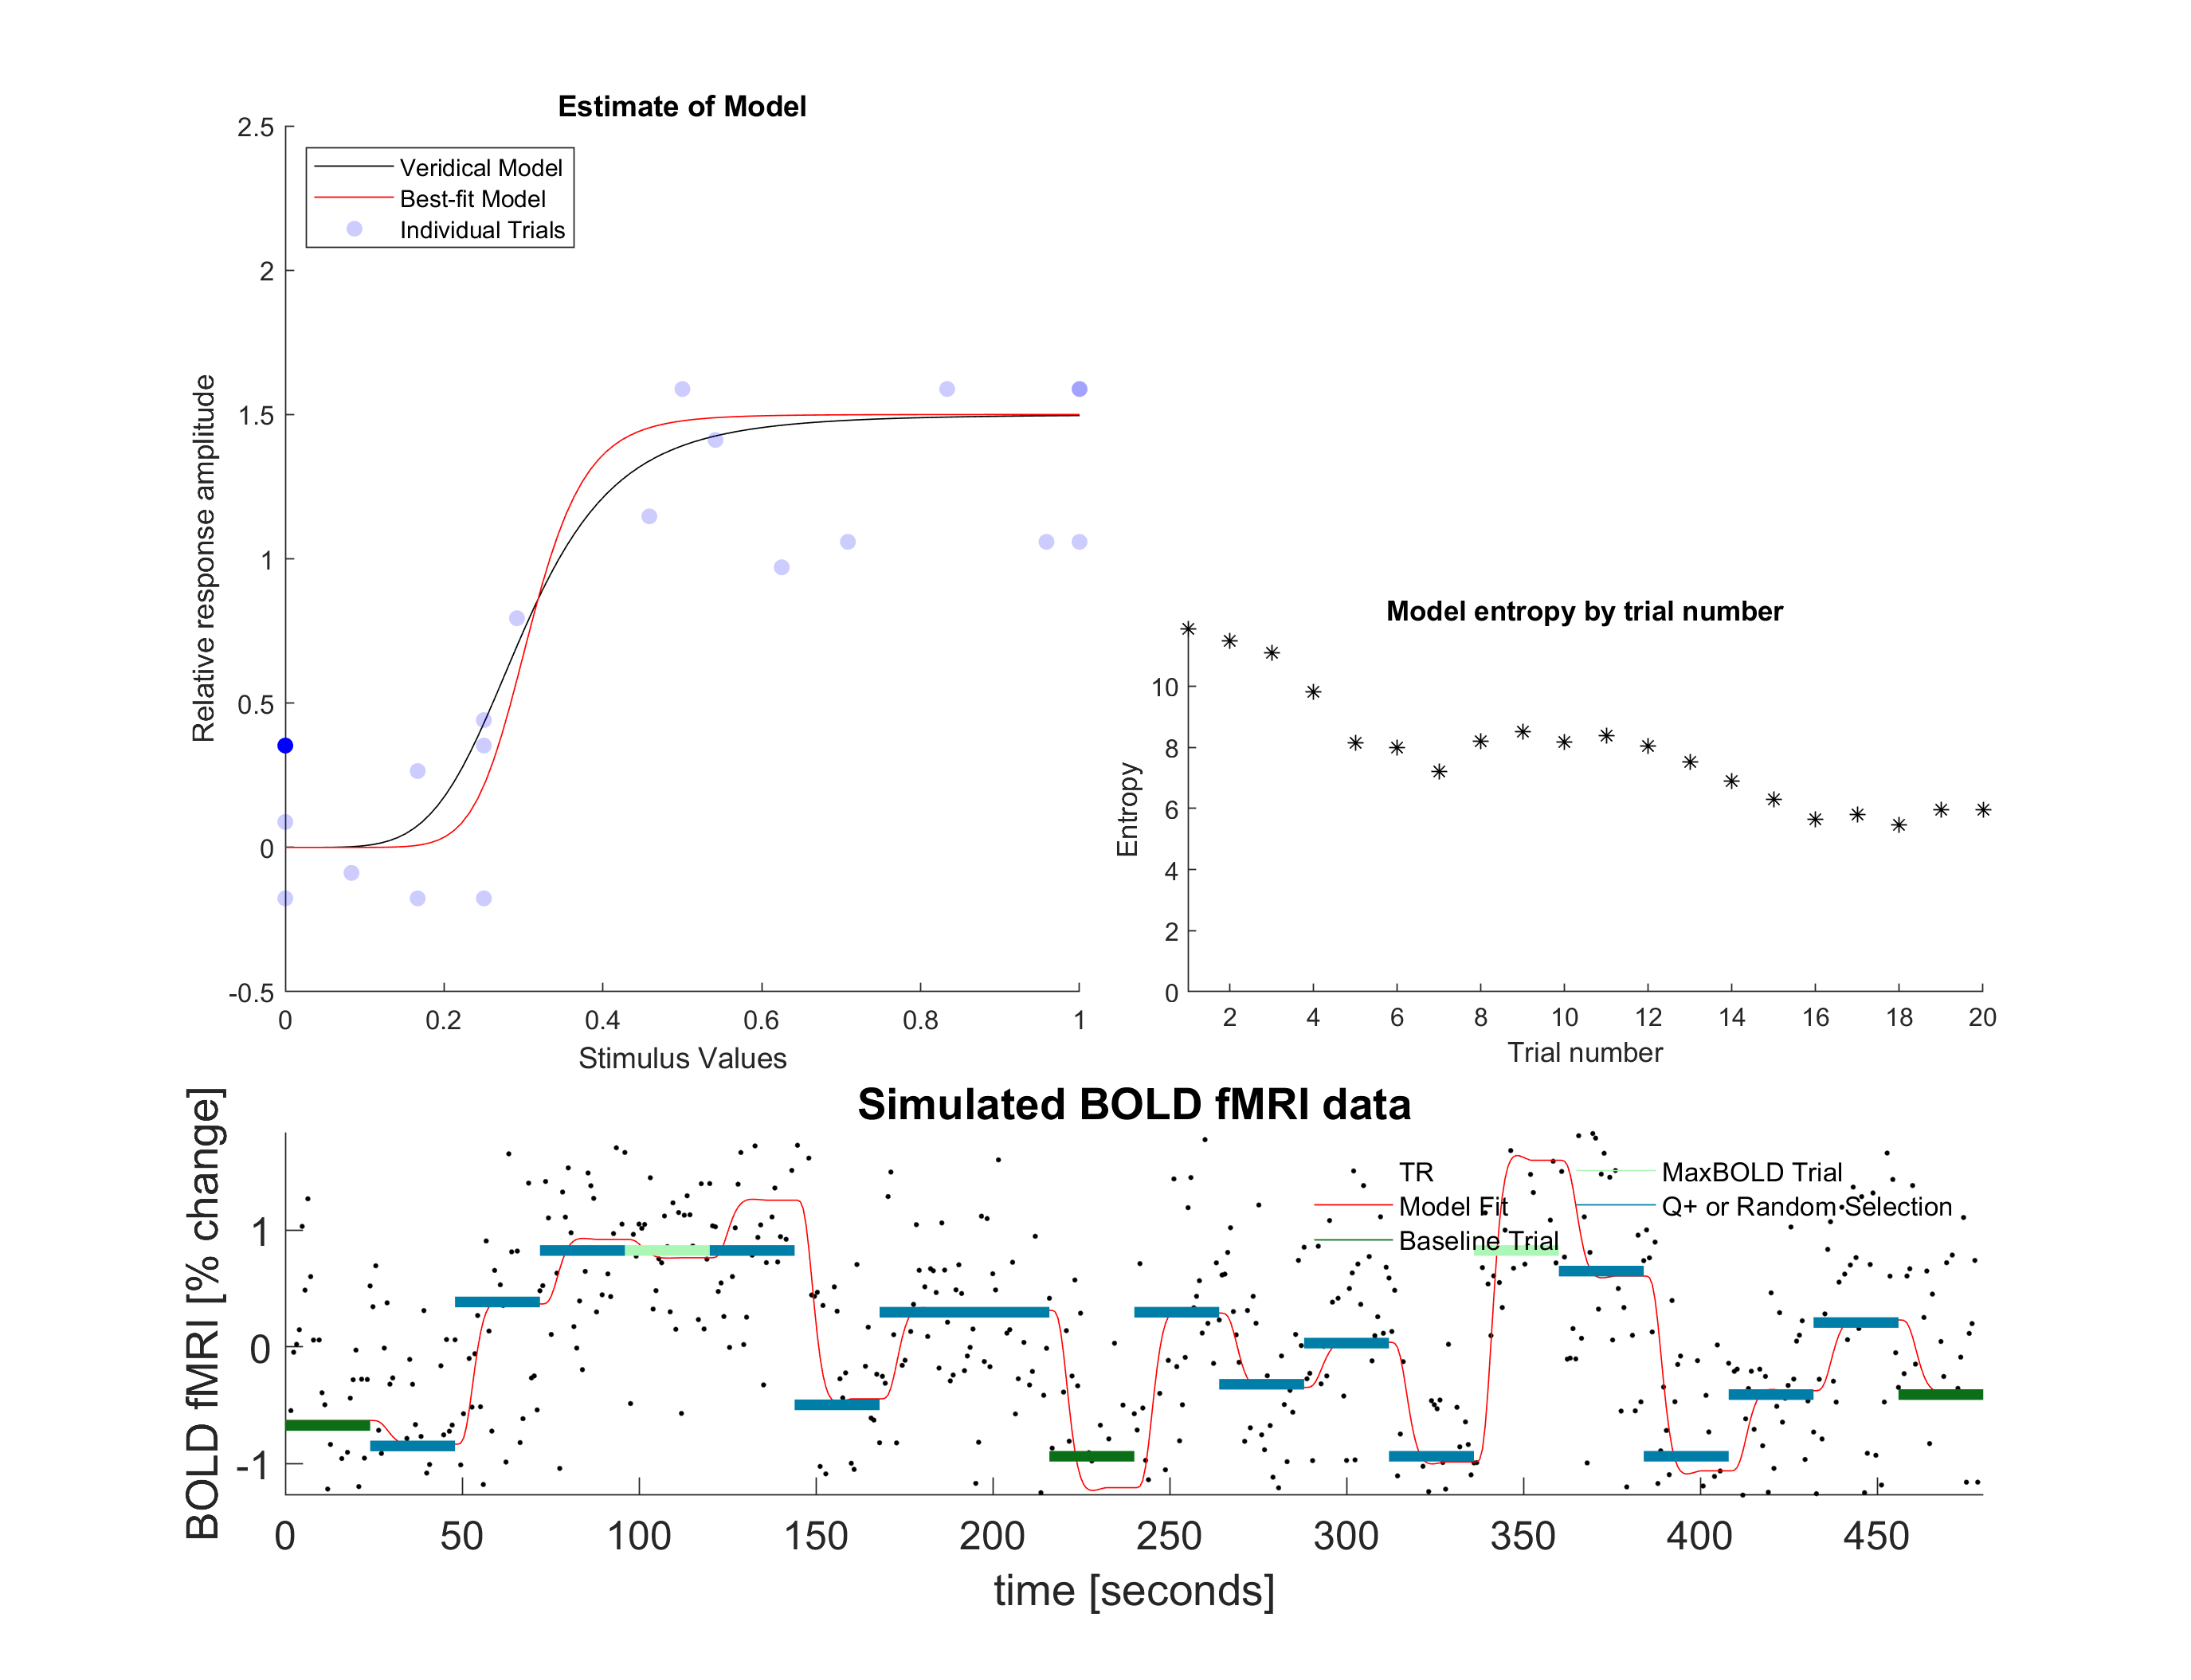


[qpfmriResults,questDataFalse]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots,'saveFigs',true);

Initial random call 0.3315
Random call after seed 0.4375


Initializing Q+. This may take a minute...
Elapsed time is 0.598316 seconds.


Simulated parameters:
exponent: 5.000 semiSat: 0.300 beta: 1.000 sigma: 0.010 
Noise in the simulation is set at 0.900 relative to a maxBOLD of 1.50

Trial 1: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 0.517 semiSat: 0.100 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 2: qplus Stimulus Selection
Stimulus: 0.458
Output value 1.059

Q+ parameters
exponent: 0.517 semiSat: 0.100 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 3: qplus Stimulus Selection
Stimulus: 0.208
Output value -0.176

Q+ parameters
exponent: 9.568 semiSat: 0.418 beta: 1.000 sigma: 0.057 
maxBOLD estimate = 1.500




Trial 4: qplus Stimulus Selection
Stimulus: 0.708
Output value 1.500

Q+ parameters
exponent: 8.336 semiSat: 0.413 beta: 1.000 sigma: 0.050 
maxBOLD estimate = 1.500




Trial 5: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.500

Q+ parameters
exponent: 9.998 semiSat: 0.421 beta: 1.000 sigma: 0.051 
maxBOLD estimate = 1.500




Trial 6: qplus Stimulus Selection
Stimulus: 0.375
Output value 1.412

Q+ parameters
exponent: 8.011 semiSat: 0.298 beta: 1.000 sigma: 0.088 
maxBOLD estimate = 1.500




Trial 7: qplus Stimulus Selection
Stimulus: 0.292
Output value 0.618

Q+ parameters
exponent: 9.997 semiSat: 0.296 beta: 1.000 sigma: 0.101 
maxBOLD estimate = 1.500




Trial 8: qplus Stimulus Selection
Stimulus: 0.417
Output value 0.882

Q+ parameters
exponent: 10.000 semiSat: 0.296 beta: 1.000 sigma: 0.151 
maxBOLD estimate = 1.500




Trial 9: qplus Stimulus Selection
Stimulus: 0.250
Output value -0.176

Q+ parameters
exponent: 10.000 semiSat: 0.300 beta: 1.000 sigma: 0.183 
maxBOLD estimate = 1.500




Trial 10: baseline Stimulus Selection
Stimulus: 0.000
Output value -0.176

Q+ parameters
exponent: 7.746 semiSat: 0.276 beta: 1.000 sigma: 0.129 
maxBOLD estimate = 1.500




Trial 11: qplus Stimulus Selection
Stimulus: 0.250
Output value 0.088

Q+ parameters
exponent: 9.982 semiSat: 0.294 beta: 1.000 sigma: 0.123 
maxBOLD estimate = 1.500




Trial 12: qplus Stimulus Selection
Stimulus: 0.375
Output value 1.235

Q+ parameters
exponent: 9.988 semiSat: 0.277 beta: 1.000 sigma: 0.119 
maxBOLD estimate = 1.500




Trial 13: qplus Stimulus Selection
Stimulus: 0.250
Output value 0.882

Q+ parameters
exponent: 10.000 semiSat: 0.263 beta: 1.000 sigma: 0.144 
maxBOLD estimate = 1.500




Trial 14: qplus Stimulus Selection
Stimulus: 0.250
Output value 0.088

Q+ parameters
exponent: 9.967 semiSat: 0.278 beta: 1.000 sigma: 0.130 
maxBOLD estimate = 1.500




Trial 15: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.588

Q+ parameters
exponent: 7.956 semiSat: 0.275 beta: 1.000 sigma: 0.112 
maxBOLD estimate = 1.500




Trial 16: qplus Stimulus Selection
Stimulus: 0.250
Output value 0.618

Q+ parameters
exponent: 9.996 semiSat: 0.270 beta: 1.000 sigma: 0.117 
maxBOLD estimate = 1.500




Trial 17: qplus Stimulus Selection
Stimulus: 0.250
Output value -0.176

Q+ parameters
exponent: 8.649 semiSat: 0.283 beta: 1.000 sigma: 0.138 
maxBOLD estimate = 1.500




Trial 18: qplus Stimulus Selection
Stimulus: 0.375
Output value 1.235

Q+ parameters
exponent: 10.000 semiSat: 0.277 beta: 1.000 sigma: 0.139 
maxBOLD estimate = 1.500




Trial 19: qplus Stimulus Selection
Stimulus: 0.375
Output value 0.971

Q+ parameters
exponent: 8.451 semiSat: 0.283 beta: 1.000 sigma: 0.148 
maxBOLD estimate = 1.500




Trial 20: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.353

Q+ parameters
exponent: 7.522 semiSat: 0.321 beta: 1.000 sigma: 0.158 
maxBOLD estimate = 1.500



--------------------------------------------------------------
FINAL VALUES
--------------------------------------------------------------
Simulated parameters:              exponent: 5.000 semiSat: 0.300 beta: 1.000 sigma: 0.010 
Max posterior QUEST+ parameters:   exponent: 5.179 semiSat: 0.357 beta: 1.000 sigma: 0.166 
Max BADS parameters:               exponent: 7.396 semiSat: 0.320 beta: 1.000 sigma: 0.158 
maxBOLD estimate: 1.500


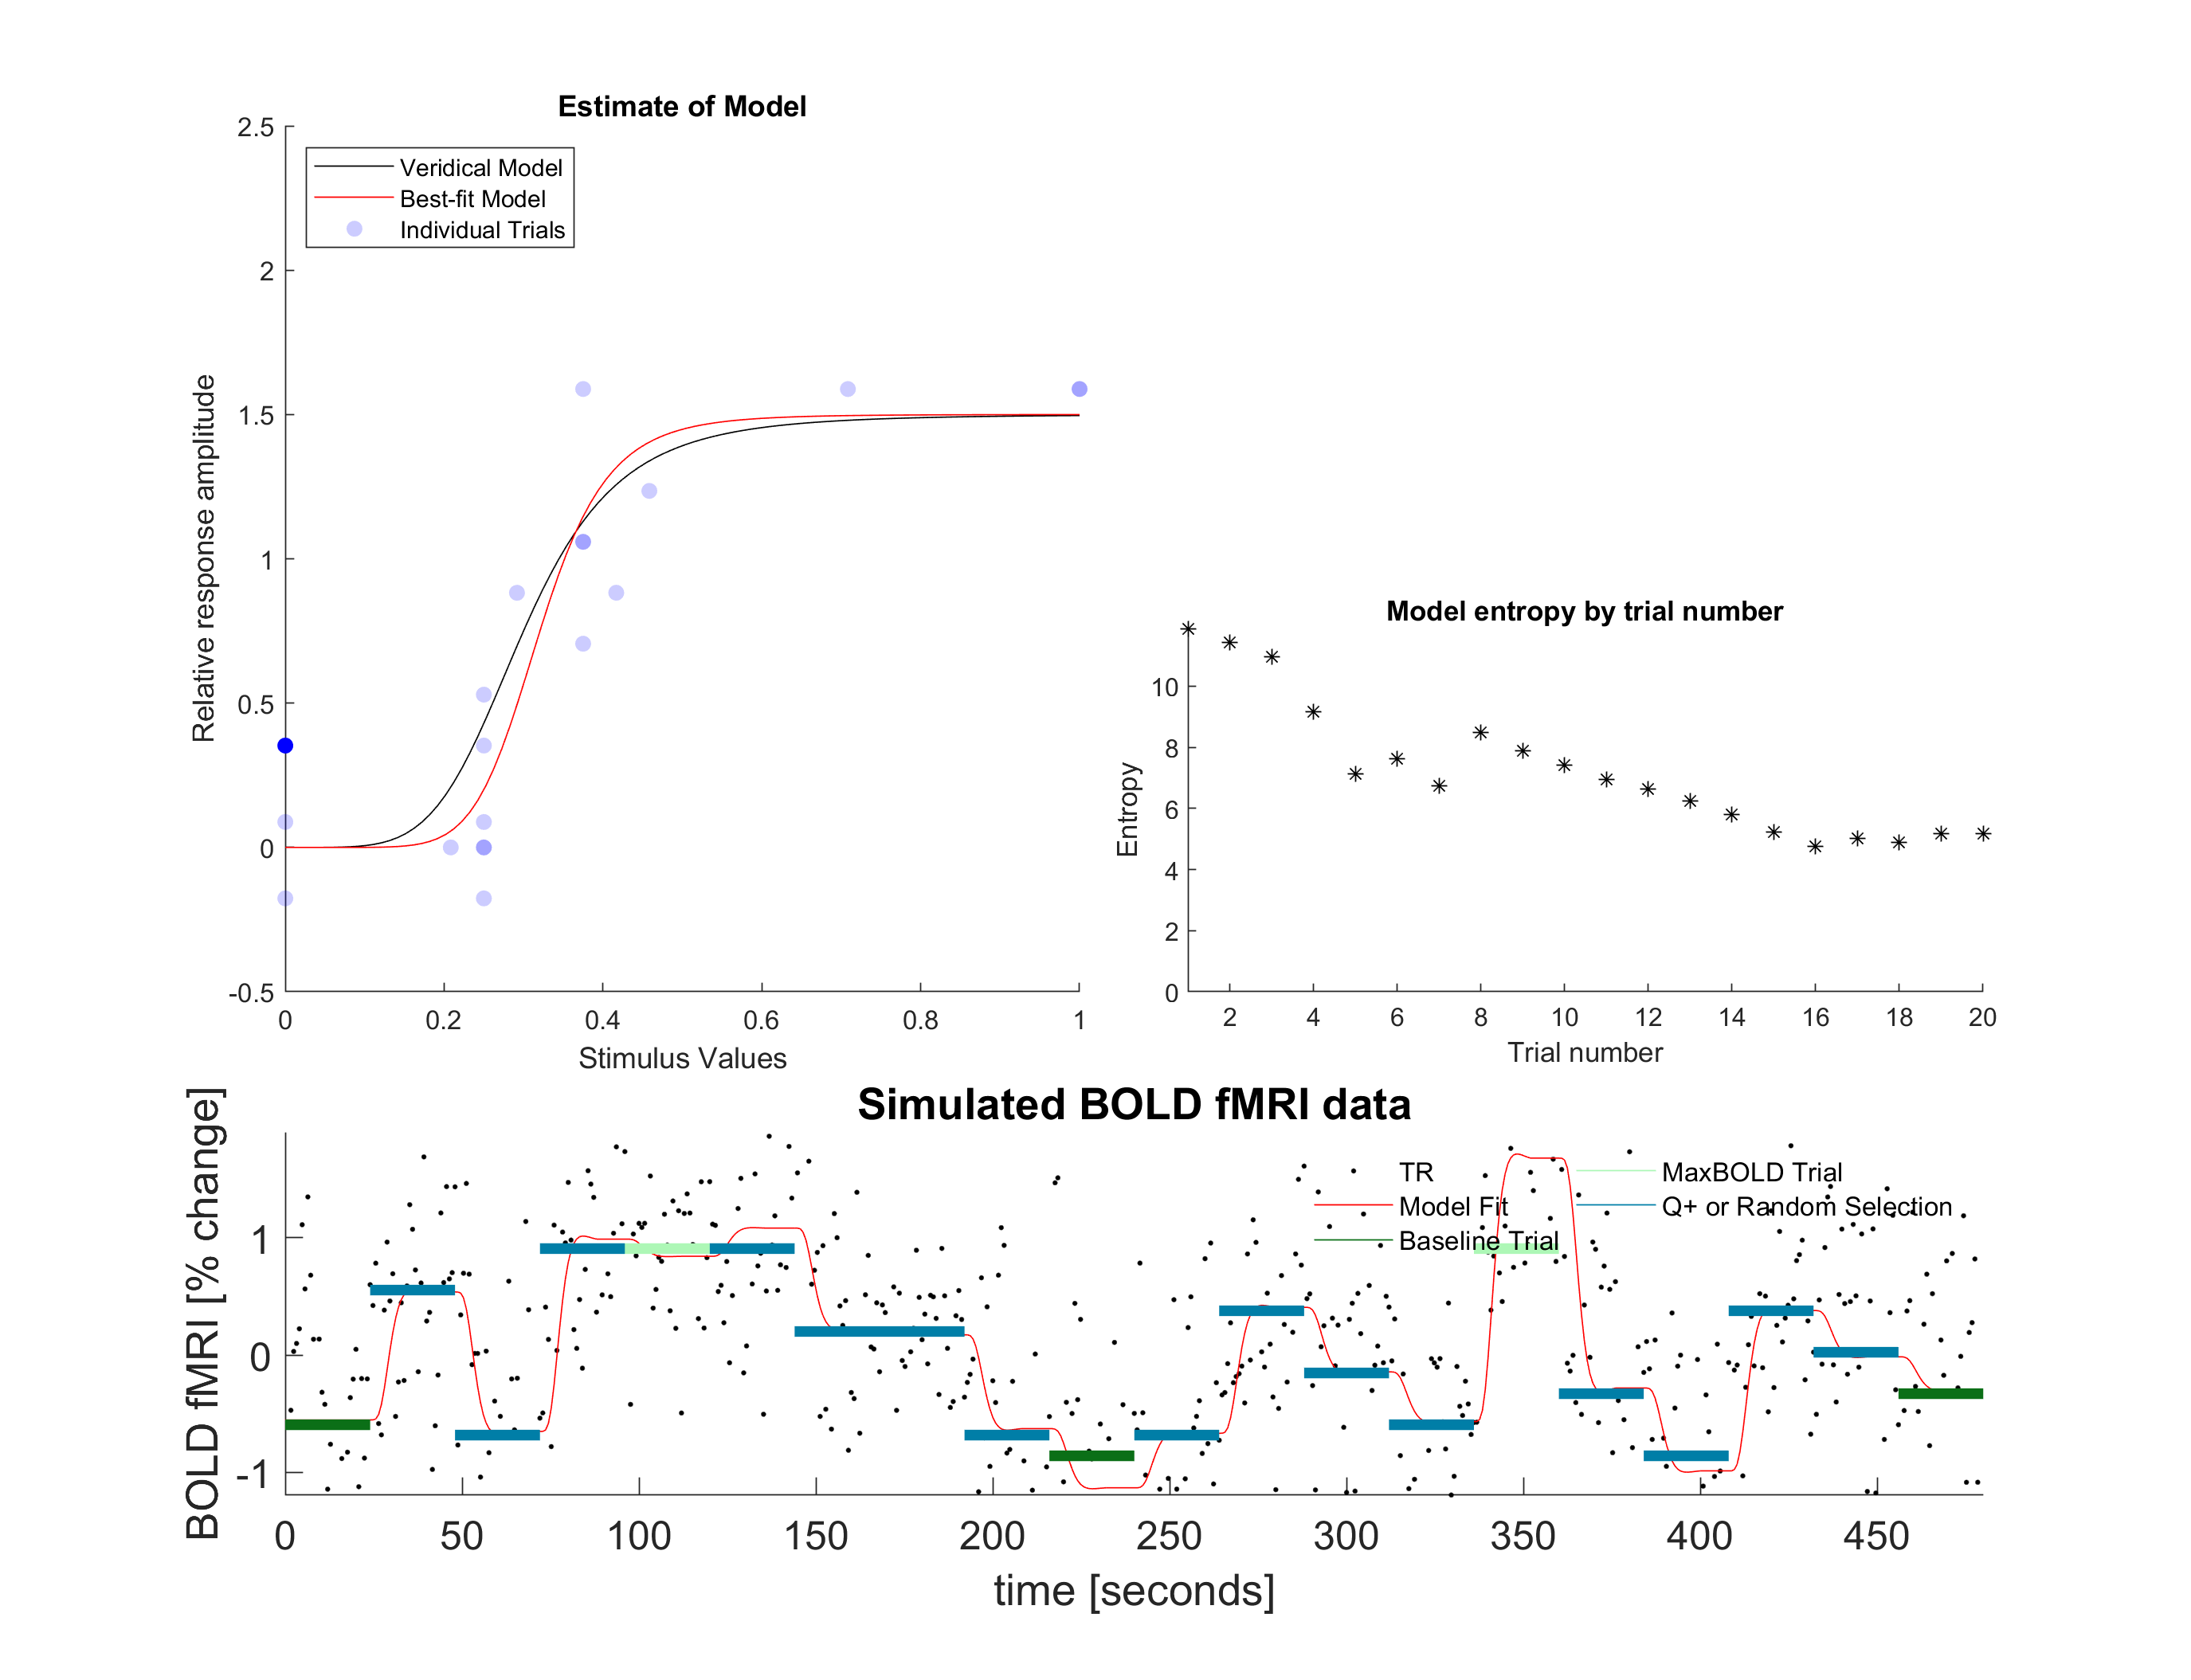


qpPres = true;

% Save outNum based on values
outNum = sprintf(formatSpec,pinkNoise,noiseSD,num2str(qpPres),nOutcomes,nTrials,seed,date);

[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'pinkNoise',pinkNoise,'baselineStimulus',baselineStimulus,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams,...,
'outFolder',outFolder,'outNum',outNum);

[qpfmriResults,questDataFalse]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots,'saveFigs',true);

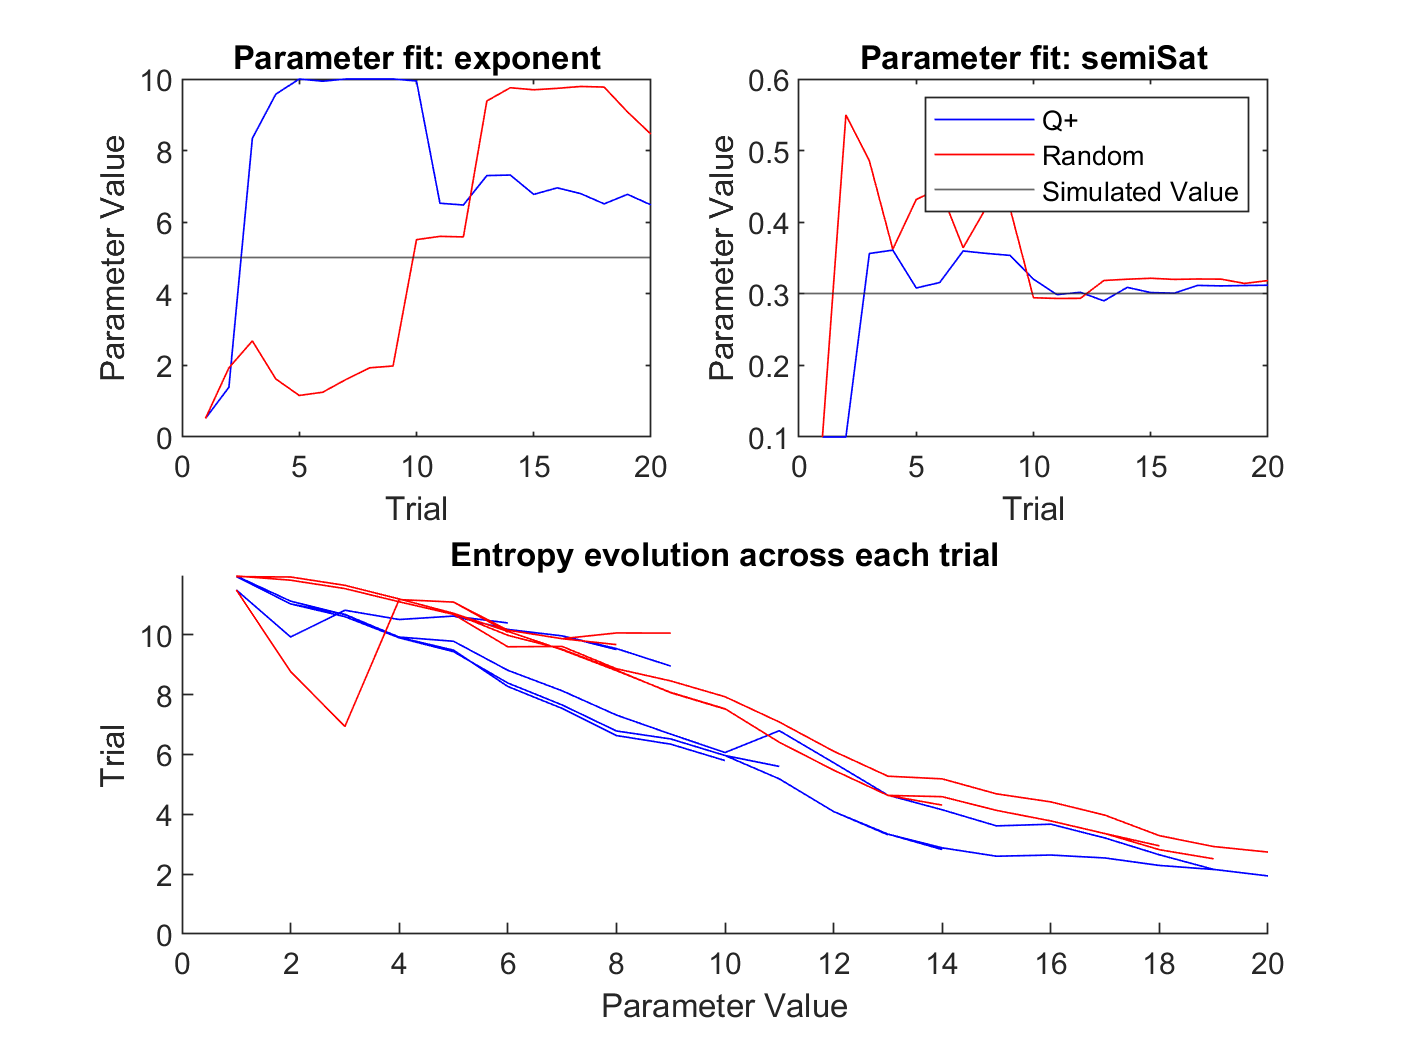

qpYesStem = sprintf(formatSpec,pinkNoise,noiseSD,'1',nOutcomes,nTrials,seed,date);
qpYesResults = [outFolder filesep 'sim_' qpYesStem '.mat'];
qpNoStem = sprintf(formatSpec,pinkNoise,noiseSD,'0',nOutcomes,nTrials,seed,date);
qpNoResults = [outFolder filesep 'sim_' qpNoStem '.mat'];


if isfile(qpYesResults) && isfile(qpNoResults)
    qpYes = load(qpYesResults);
    qpNo = load(qpNoResults);
end


% Extract Parameter names
paramNames = fieldnames(qpYes.qpfmriResults.paramsDomain);

% Create figure to show fits of parameters
outcomeFigure = figure; 

% Plot first parameter
subplot(2,2,1);
plot(qpYes.qpfmriResults.psiParamsBADS(:,1),'b'); 
hold on; 
plot(qpNo.qpfmriResults.psiParamsBADS(:,1),'r'); 
yline(qpYes.qpfmriResults.simulatedPsiParams(1)); 
title(sprintf('Parameter fit: %s',paramNames{1}));
ylabel('Parameter Value') 
xlabel('Trial') 

% Plot second parameter
subplot(2,2,2);
plot(qpYes.qpfmriResults.psiParamsBADS(:,2),'b'); 
hold on; 
plot(qpNo.qpfmriResults.psiParamsBADS(:,2),'r'); 
yline(qpYes.qpfmriResults.simulatedPsiParams(2)); 
title(sprintf('Parameter fit: %s',paramNames{2}));
legend('Q+','Random', 'Simulated Value');
ylabel('Parameter Value') 
xlabel('Trial') 


subplot(2,2,[3,4]);
hold on; 
for i = 1:length(qpYes.qpfmriResults.entropyOverTrials)
    plot(qpYes.qpfmriResults.entropyOverTrials{i},'b');
end
for i = 1:length(qpNo.qpfmriResults.entropyOverTrials)
    plot(qpNo.qpfmriResults.entropyOverTrials{i},'r');
end
title(sprintf('Entropy evolution across each trial'));
ylabel('Trial') 
xlabel('Parameter Value') 


set(outcomeFigure,'Units','Inches');
pos = get(outcomeFigure,'Position');
set(outcomeFigure,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)]);
print(outcomeFigure,fullfile(outFolder,[myQpfmriParams.outNum '_simulate_outcome.pdf']),'-dpdf','-r0');

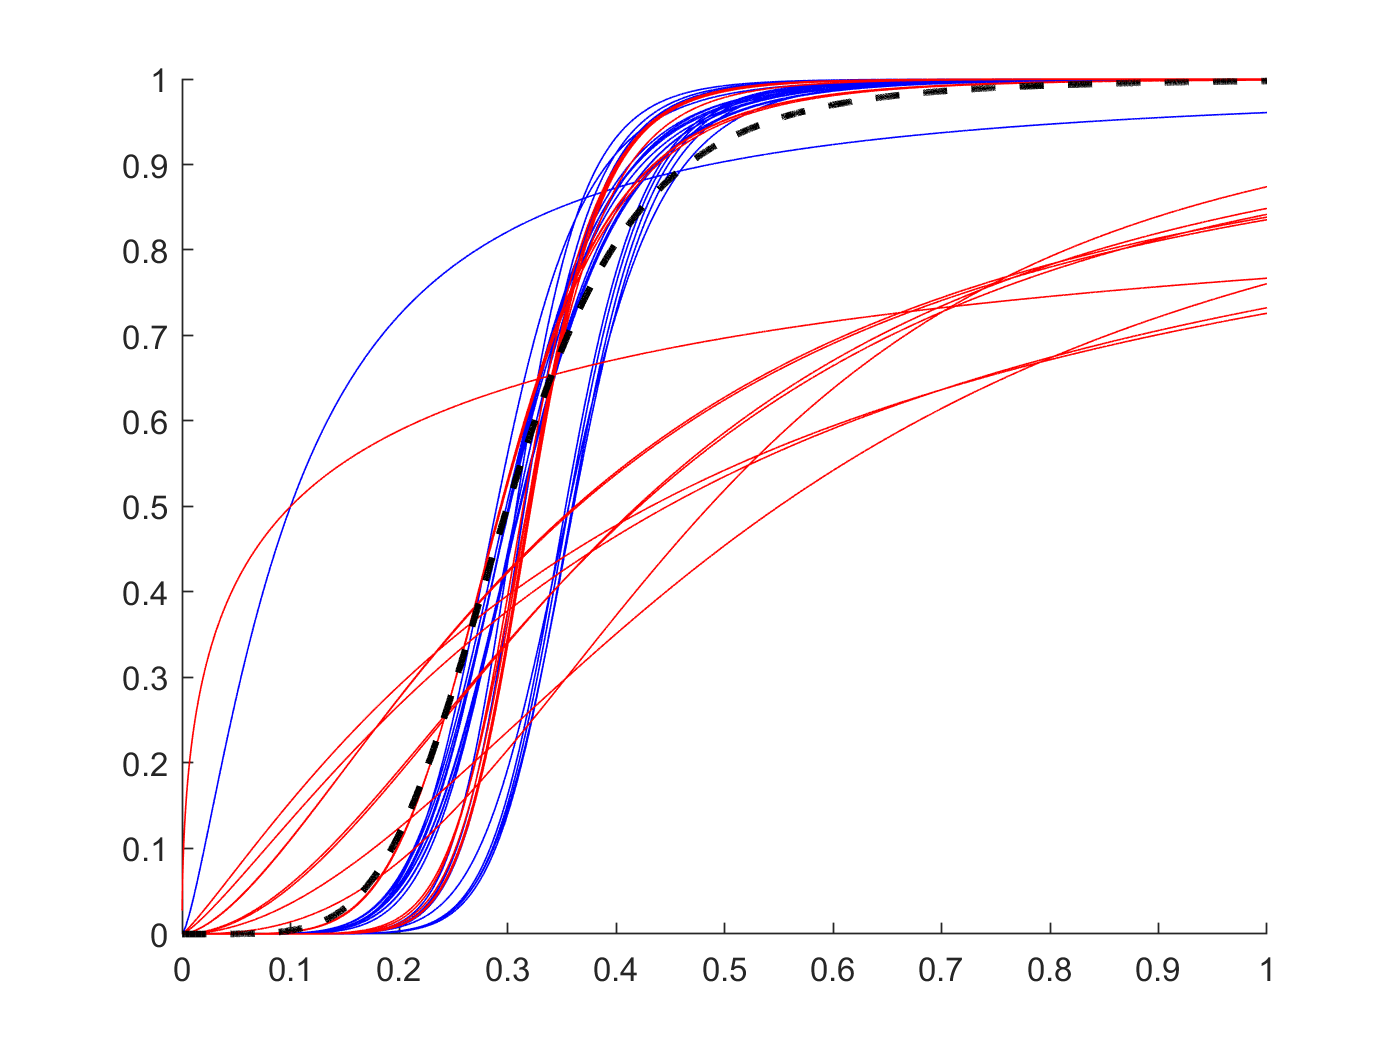

figure;
hold on; 

stimulusDomainFine = (min(cell2mat(qpYes.qpfmriResults.stimulusDomain)):.0001:max(cell2mat(qpYes.qpfmriResults.stimulusDomain)));

for i = 1:qpYes.qpfmriResults.nTrials
    plot(stimulusDomainFine,...,
         qpYes.qpfmriResults.model(stimulusDomainFine,qpYes.qpfmriResults.psiParamsBADS(i,:)),'-b');
end
for i = 1:qpNo.qpfmriResults.nTrials
    plot(stimulusDomainFine,...,
         qpNo.qpfmriResults.model(stimulusDomainFine,qpNo.qpfmriResults.psiParamsBADS(i,:)),'-r');
end
plot(stimulusDomainFine,qpYes.qpfmriResults.model(stimulusDomainFine,qpYes.qpfmriResults.simulatedPsiParams(1,:)),'--k','LineWidth',2);